rng(0);
clear;

Consider the dataset provided within the folder “data_fruit” For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. Each datum is an image of size 80 × 80 pixels with 3 color channels red (R), green (G), and blue (B), i.e., a 80 × 80 × 3 array. For PCA, each image should be resized to a vector of length 19200. For visualization, reshape each vector back to a RGB image of size 80 × 80 pixels using the function reshape(), followed by a shift and rescaling of the values into the range [0, 1], followed by displaying the matrix using the function image(). 

Imgs = readall(imageDatastore('data_fruit/*.png'));
[imgsz,~] = size(Imgs);
imgs = zeros(80*80*3,imgsz);
for i = 1:imgsz
    imgs(:,i) = double(reshape(Imgs{i},19200,1))/255;
end

• (9 points: 1 + 4 + 4) Similar to the analysis done in previous question, find the mean µ, the covariance matrix C, and the top 4 principle eigenvectors of C. Display the mean and the eigenvectors as images (side by side, in the same figure); you can use the function subplot(). Find the top 10 eigenvalues, sort them, and plot their values on a graph. Use the function eigs() for efficient computation. 

mu = sum(imgs,2)/imgsz

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


shiftimg = imgs - mu;
C = shiftimg*shiftimg'/imgsz; % cov

[Q, D] = eigs(C, 10); % eigs(C, k) gets the k largest eigenvals and corresponding eigenvectors
D = diag(D);    %top 10 eigenvals
D

D =   201.5754
  187.3928
  134.6039
   87.4595
   64.9140
   43.3435
   38.4250
   28.0355
   23.5461
   18.0182



Q = Q(:, 1:4)   %only first 4 eigenvecs

Q =     0.0154    0.0005   -0.0057    0.0056
    0.0152    0.0012   -0.0051    0.0060
    0.0151    0.0012   -0.0046    0.0063
    0.0156    0.0002   -0.0053    0.0052
    0.0159    0.0007   -0.0056    0.0050
    0.0159    0.0010   -0.0065    0.0053
    0.0155    0.0006   -0.0079    0.0050
    0.0154    0.0005   -0.0082    0.0049
    0.0159    0.0006   -0.0081    0.0052
    0.0148   -0.0000   -0.0080    0.0055


figure,
subplot(1,5,1);
imagesc(reshape(mu, 80, 80, 3))'

ans =   Image with properties:

           CData: [80×80×3 double]
    CDataMapping: 'scaled'

  Show all properties


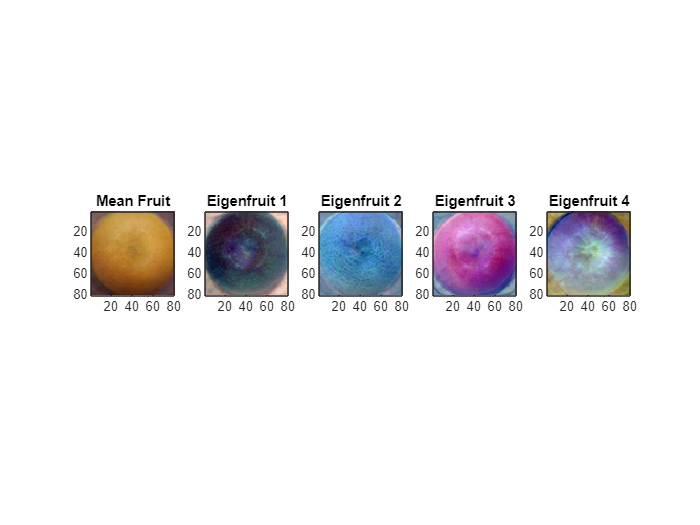

title("Mean Fruit");
pbaspect([1,1,1])
for i = 1:4
    subplot(1,5,i+1);
    imagesc(reshape(rescale(Q(:, i)), 80, 80, 3));
    pbaspect([1,1,1]);
    title("Eigenfruit "+i);
end

hold off

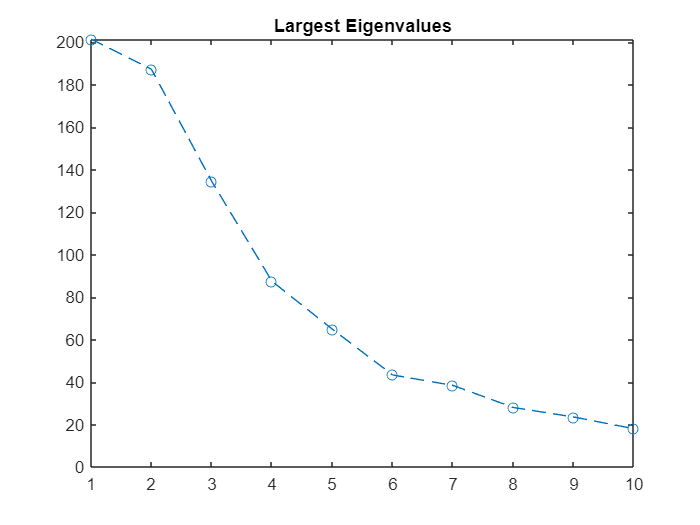


figure
plot(1:10, D,'o--');
title("Largest Eigenvalues");

• (8 points: 4 + 4) For each fruit image in the dataset, finds its closest representation as a linear combination of the top 4 eigenvectors added to the mean. Use the measure of closeness as the Frobenius norm of the difference. Describe the algorithm used to produce this closest representation in mathematical terms and describe the logic behind your algorithm. Display the original fruit image and its closest representation, as images (side by side, in the same figure). 

Observe that each fruit image is a vector with 19200 dimensions. Since the convariance matrix is symmetric, from the **Spectral Theorem**, we know that it has 19200 orthogonlaeigenvectors

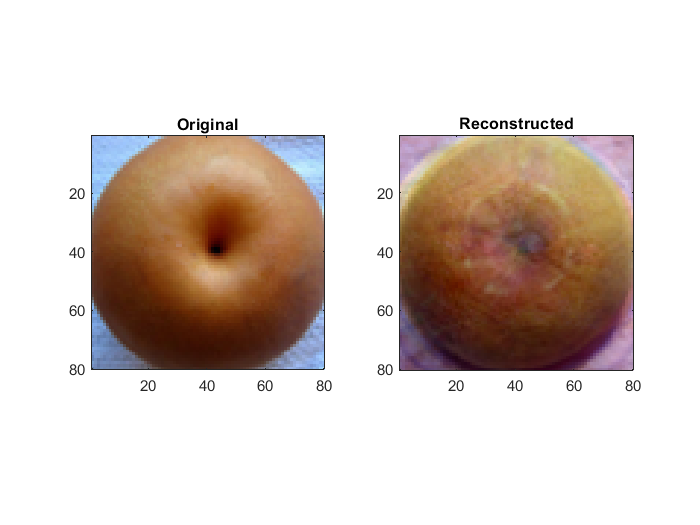

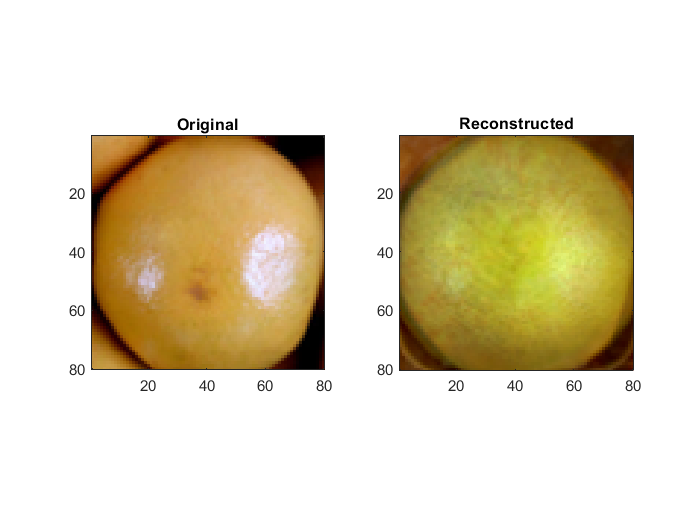

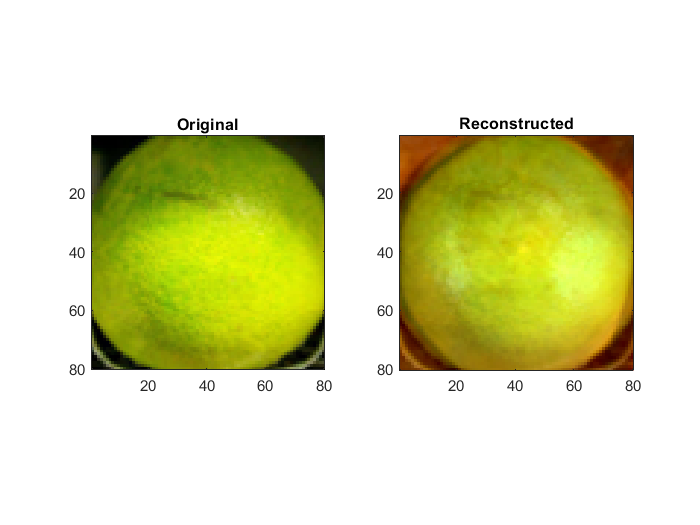

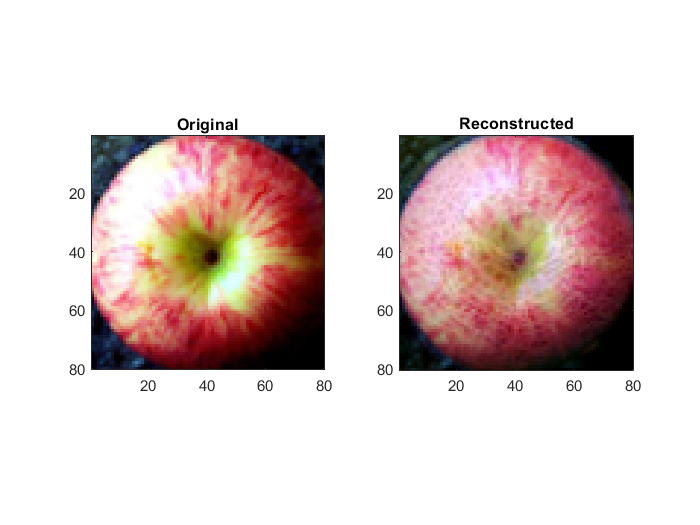

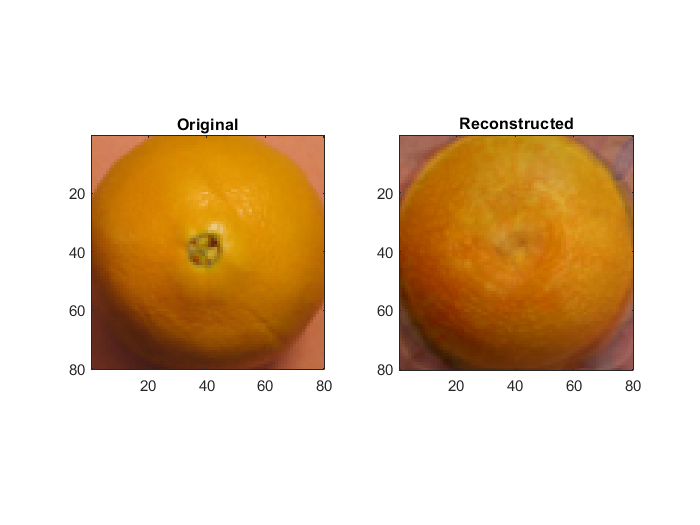

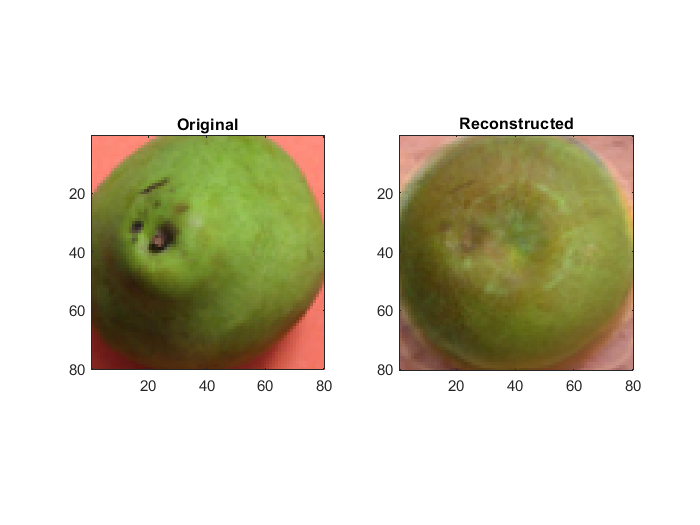

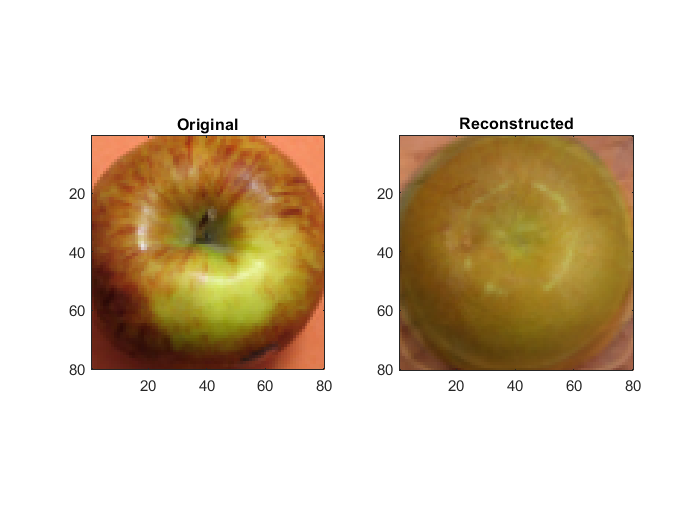

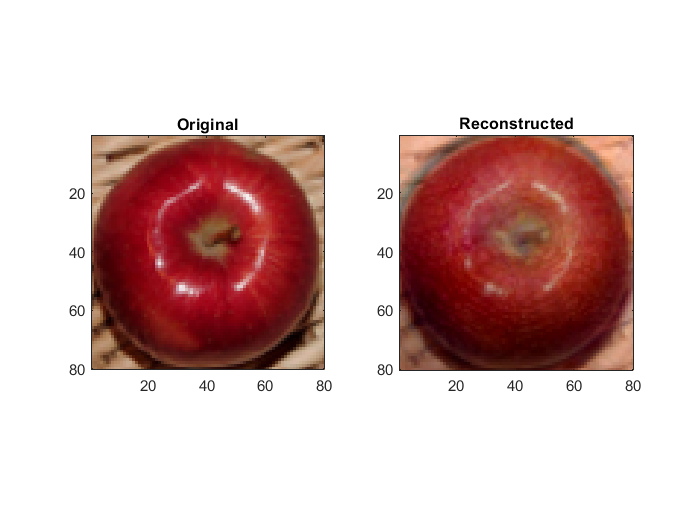

close_rep_mat = mu + Q*Q'*shiftimg;

for i = 1:imgsz
    pause(0.01)
    figure,
    subplot(1,2,1);
    imagesc(reshape(imgs(:,i), 80, 80, 3));
    title("Original");
    pbaspect([1,1,1]);

    subplot(1,2,2);
    imagesc(reshape(close_rep_mat(:,i), 80, 80, 3));
    title("Reconstructed");
    pbaspect([1,1,1]);

end

• (9 points: 3 + 3 + 3) Using all of the top 4 eigenvectors and the mean image, sample random images to generate new images of "fruit". Describe the underlying algorithm clearly in words and including suitable mathematical notation. Display three such images that are distinct from any image in the given the dataset, but are representative of the dataset and can be considered as that of a new / generated fruit.

mu % mean

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


D=D(1:4) % top 4 eigenvalues

D =   201.5754
  187.3928
  134.6039
   87.4595


Q % corresponding eigenvectors

Q =     0.0154    0.0005   -0.0057    0.0056
    0.0152    0.0012   -0.0051    0.0060
    0.0151    0.0012   -0.0046    0.0063
    0.0156    0.0002   -0.0053    0.0052
    0.0159    0.0007   -0.0056    0.0050
    0.0159    0.0010   -0.0065    0.0053
    0.0155    0.0006   -0.0079    0.0050
    0.0154    0.0005   -0.0082    0.0049
    0.0159    0.0006   -0.0081    0.0052
    0.0148   -0.0000   -0.0080    0.0055


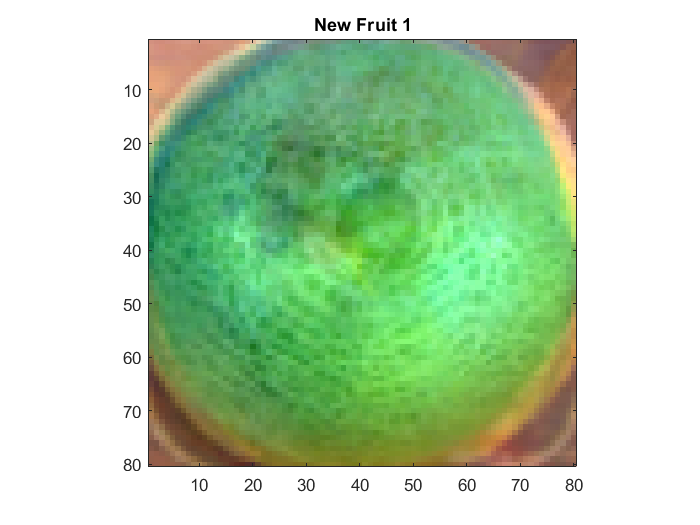

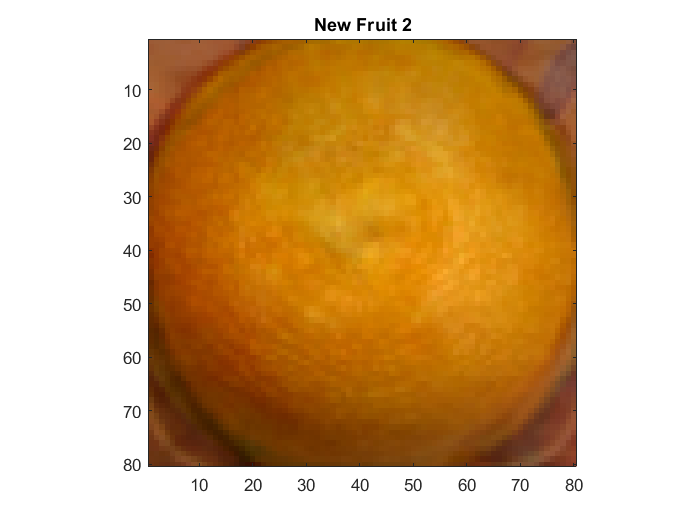

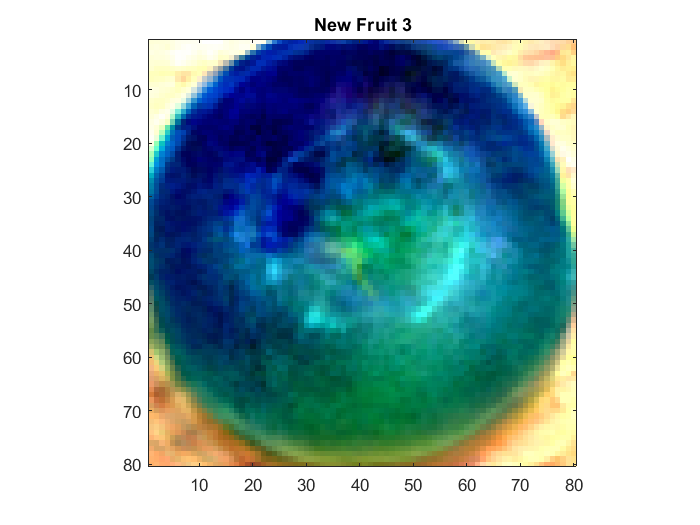


for i=(1:3)
    nimg = mu + Q*diag(sqrt(D))*randn(4,1);
    figure,
    imagesc(reshape(nimg,80,80,3));
    title("New Fruit "+i);
    pbaspect([1,1,1]);
end